fid = fopen('blurred_img_psf.raw', 'rb');
A = fread(fid, [256, 512], 'float');
fclose(fid);
img = A(1:256,1:256);
psf = A(1:256,257:512);

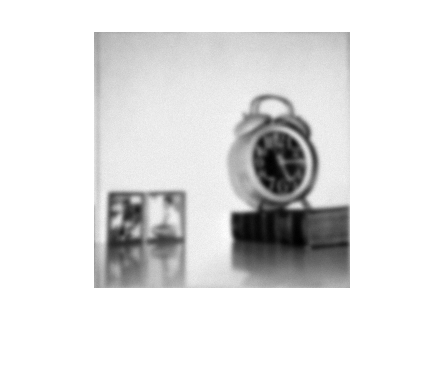

imshow(img,[])

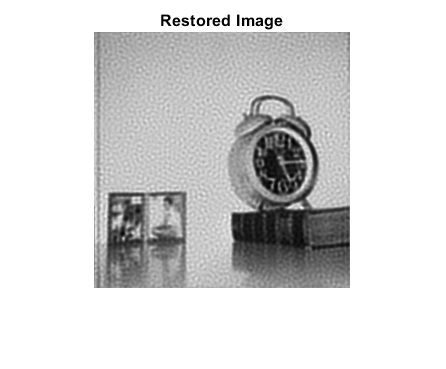

luc1 = deconvlucy(img,psf,50);
imshow(luc1,[])
title('Restored Image')

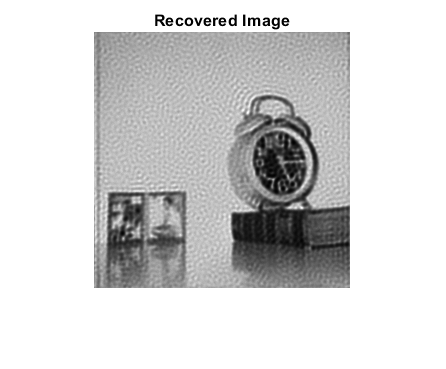

res_RL = RL_deconv(img, psf, 500); 
figure; imshow(res_RL,[]); title('Recovered Image')

A = magic(5);
A1 = psf2otf(A,size(A));
A2 = fft2(ifftshift(A))

A2 = 	1.0e+02 *

   3.2500 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 1.0633i   0.0000 - 0.2127i   0.0000 - 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.6572i   0.0000 + 0.0000i   0.0000 + 0.1314i
   0.0000 - 0.0000i   0.0000 - 0.1314i   0.0000 + 0.0000i   0.0000 - 0.6572i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.2127i   0.0000 + 1.0633i


function result = RL_deconv(image, PSF, iterations)
fn = image; % at the first iteration
% OTF = psf2otf(PSF,size(image));
OTF = fft2(ifftshift(PSF));
for i=1:iterations
    ffn = fft2(fn); 
    Hfn = OTF.*ffn; 
    iHfn = ifft2(Hfn); 
    ratio = image./iHfn; 
    iratio = fft2(ratio); 
    res = OTF .* iratio; 
    ires = ifft2(res); 
    fn = ires.*fn; 
end
result = abs(fn); 
end